# Figure 1

# %% load img

rawFile = 'C:\Users\Bergles Lab\Desktop\temp\Experiment-330-P8-Snap25GC6s_baseline.tif';
pathStr = fileparts(rawFile);
img = loadTif(rawFile,16);

norm = normalizeImg(img,10,1);

Bleach correction finished. Subtracting baseline...


images = [1826; 1906; 1921; 1955; 2003; 2025; 2058];
filt = imgaussfilt3(norm(:,:,3000:5996));


## graph img

%rawFile = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure1\Data\Timeseries\Experiment-569_P6-Snap25GC6s.tif';
%img = loadTif(rawFile,16);
%norm = normalizeImg(img(:,:,1:3000),10,1);
%filt = imgaussfilt3(norm);

norm = normalizeImg(img(:,:,2000:2400),10,1);

Bleach correction finished. Subtracting baseline...


filt = imgaussfilt3(norm);
times = [322 372];

times_v = [times(1):5:times(2)];
figure(4)
m = size(times_v,2);
low = -.1; hi = 0.8;
for i = 1:(m-3)
    subplot(1,m-3,i);
    imagesc(filt(1:200,:,times_v(i)));
    box off; axis off;
    colormap(gfb);
    caxis([low hi]);
    UL=[512*m 300];
    po=get(gcf,'position');
    po(3:4)=UL;
    set(gcf,'position',po);
    %imwrite([pathStr '\' num2str(i) '.tif'],
end

norm = normalizeImg(img(:,:,500:1000),10,1);

Bleach correction finished. Subtracting baseline...


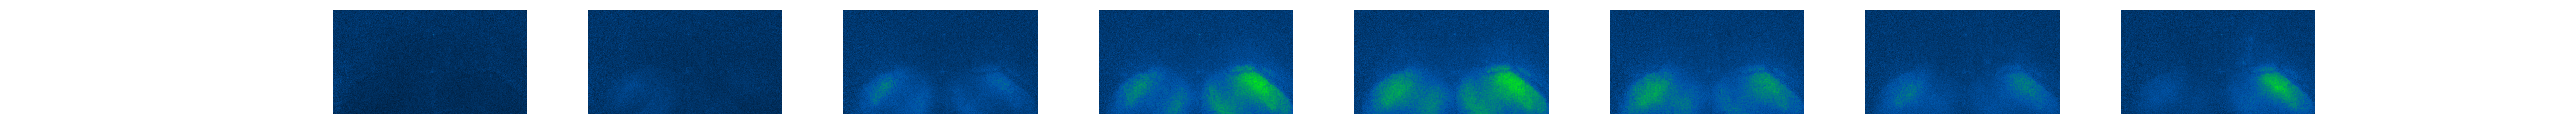

filt = imgaussfilt3(norm);
times = [292 342];

times_v = [times(1):5:times(2)];
figure(4)
m = size(times_v,2);
for i = 1:m-3
    subplot(1,m-3,i);
    imagesc(filt(1:200,:,times_v(i)));
    box off; axis off;
    colormap(gfb);
    caxis([low hi]);
    UL=[512*m 300];
    po=get(gcf,'position');
    po(3:4)=UL;
    set(gcf,'position',po);
end

## Signal plots

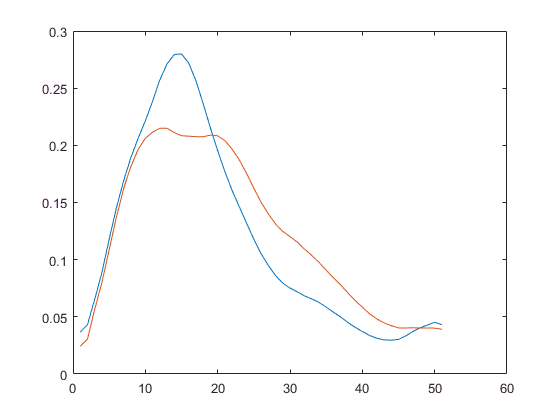



file = 'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
load(file);
figure;
plot([smooth(ICsignal([times(1)+2000:times(2)+2000],1)) smooth(ICsignal([times(1)+2000:times(2)+2000],2))]); hold on;

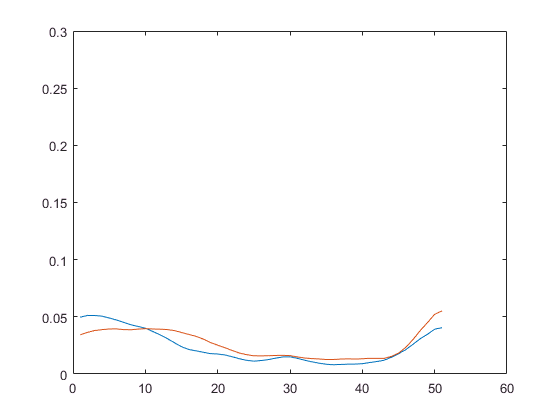



figure;
plot([smooth(ICsignal([times(1):times(2)]+500,1)) smooth(ICsignal([times(1):times(2)]+500,2))]); ylim([0 .3]);

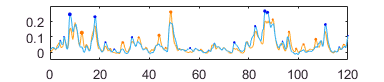


LIC = smooth(ICsignal(:,1));
RIC = smooth(ICsignal(:,2));
ctx = smooth(ICsignal(:,3));
time = [1:1:size(ICsignal,1)]';
LIC = msbackadj(time,LIC,'WindowSize',500,'StepSize',500);
RIC = msbackadj(time,RIC,'WindowSize',500,'StepSize',500);
ctx = msbackadj(time,ctx,'WindowSize',500,'StepSize',500);
[m,n] = size(ICsignal);
smIC = smooth(ICsignal);
smIC = reshape(smIC,m,n);
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;
start = 1850;
endpt = 3050;
time = [1:1:(endpt-start+1)]'/10;
h = figure(5);
h.Units = 'inches';
h.Position = [5 5 4 .85];
hold off;

plot(time,LIC(start:endpt),'Color',lt_org);
ylim([-0.05 0.3])
xlim([0 120]);
hold on;
plot(time,RIC(start:endpt),'Color',lt_blue);
indices = find(pkData(:,1) >= start & pkData(:,1) <=endpt);
temp_pkData = pkData(indices,:);
[m, n] = size(temp_pkData);
temp_pkData(:,[1 3]) = (temp_pkData(:,[1 3]) - [start*ones(m,1) start*ones(m,1)])/10;
r_pkData = temp_pkData(temp_pkData(:,7)==2,:);
l_pkData = temp_pkData(temp_pkData(:,7)==1,:);
markSize = 100;
scatter(r_pkData(:,3),r_pkData(:,4),r_pkData(:,5)*markSize,dk_blue,'filled');
scatter(l_pkData(:,1),l_pkData(:,2),l_pkData(:,5)*markSize,dk_org,'filled');

## Average waveform

r_locs =     93
   158
   208
   232
   261
   336
   384
   412
   646
   720


r_locs =    183
   233
   424
   433
   449
   532
   576
   593
   688
   821


r_locs =      7
    29
    42
   164
   337
   546
   560
   638
   700
   746


r_locs =     50
    97
   263
   290
   312
   417
   476
   504
   634
   708


r_locs =     98
   159
   334
   364
   429
   670
   705
   789
   815
   828


r_locs =     14
   123
   135
   179
   216
   388
   429
   468
   496
   527


r_locs =     73
   185
   229
   291
   322
   368
   388
   479
   573
   649


r_locs =    180
   218
   409
   432
   465
   496
   582
   632
   660
   681


r_locs =    371
   405
   473
   496
   577
   616
   636
   651
   843
   949


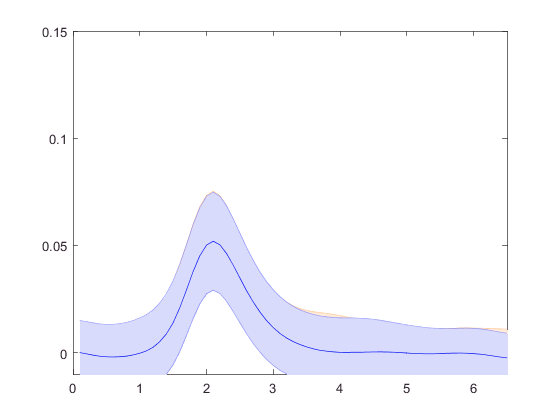

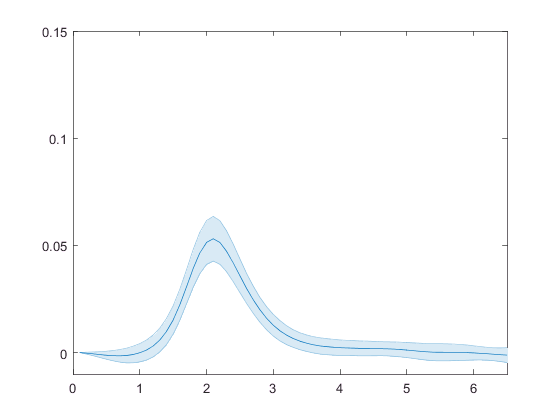

wt_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICinfo16_dFoF.mat'
            };
[avg, sterr] = waveform2(wt_paths);

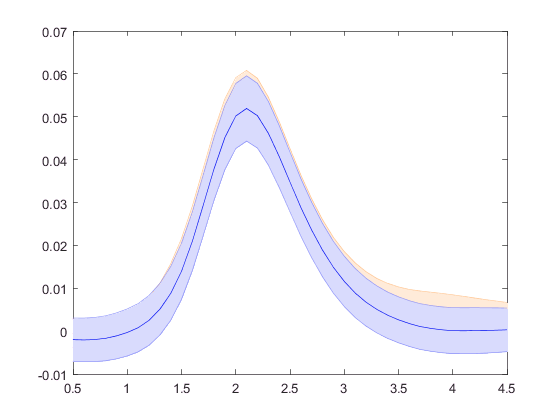

time = [(1:1:size(avg,1))/10]';
lt_org = [255, 166 , 38]/255;
    dk_org = [255, 120, 0]/255;
    lt_blue = [50, 175, 242]/255;
    dk_blue = [0, 13, 242]/255;
    
    
f = figure; 
set(f,'renderer','painters');
shadedErrorBar(time, avg(:,1), sterr(:,1),{'-','color',dk_org}); hold on;
shadedErrorBar(time, avg(:,2), sterr(:,2),{'-','color',dk_blue});
xlim([0.5 4.5]);
ylim([-0.01 .07]);

## old graph


%images = [288; 328; 368; 
% figure(3);
% box off; axis off;
% m = size(images,1);
% for i = 1:m
%     subplot(1,m,i);
%     imagesc(flipud(filt(100:450,:,images(i))));
%     box off; axis off;
%     colormap(gfb);
%     caxis([low hi]);
%     UL=[512*m 300];
%     po=get(gcf,'position');
%     po(3:4)=UL;
%     set(gcf,'position',po);
%     %imwrite([pathStr '\' num2str(i) '.tif'],
% end

%time series individual
% filt = imgaussfilt3(norm(:,:,3000:5990));
% handle = implay(filt);
% handle.Visual.ColorMap.MapExpression = 'gfb';
% handle.Visual.ColorMap.UserRangeMin = -0.1;
% handle.Visual.ColorMap.UserRangeMax = 0.8;
times = [2363 2363+36];
times_v = [times(1):6:times(2)];
figure(4)
m = size(times_v,2);

for i = 1:m
    subplot(1,m,i);
    imagesc(flipud(filt(100:450,:,times_v(i))));
    box off; axis off;
    colormap(gfb);
    caxis([low hi]);
    UL=[512*m 300];
    po=get(gcf,'position');
    po(3:4)=UL;
    set(gcf,'position',po);
    %imwrite([pathStr '\' num2str(i) '.tif'],
end

times = [1412 1412+36];
times_v = [times(1):6:times(2) 1502];
figure(5)
m = size(times_v,2);
%  filt = imgaussfilt3(norm(:,:,3000:5990));
%   handle = implay(filt);
%   handle.Visual.ColorMap.MapExpression = 'gfb';
% handle.Visual.ColorMap.UserRangeMin = -0.1;
% handle.Visual.ColorMap.UserRangeMax = 0.8;
for i = 1:m
    subplot(1,m,i);
    imagesc(flipud(filt(100:450,:,times_v(i))));
    box off; axis off;
    colormap(gfb);
    caxis([low hi]);
    UL=[512*m 300];
    po=get(gcf,'position');
    po(3:4)=UL;
    set(gcf,'position',po);
    %imwrite([pathStr '\' num2str(i) '.tif'],
end

%%correlations
% hand = figure(7);
% norm_crop = flipud(norm(100:300,:,:));
% imagesc(std(norm_crop,1,3));
% [x, y] = getpts(hand);
% x = round(x);
% y = round(y);
% [m,n,t] = size(norm_crop);
% re_normcrop = single(reshape(norm_crop,m*n,t));
% 
% for i = 1:size(x,1)
% seed = squeeze(single(norm_crop(y(i),x(i),:)));
%     corrmat = corr(seed, re_normcrop');
%     corrmatstore(:,:,i) = reshape(corrmat,m,n);
% end
% 
% low = 0;
% hi = 1;
% figure(8);
% m = size(x,1);
% for i = 1:m
%     subplot(m,1,i);
%     %axesHand = axes;
%     imagesc(corrmatstore(10:end,10:end,i));
%     box off; axis off;
%     colormap(parula);
%     caxis([low hi]);
% end
% figure(9);
% meanImg = imgaussfilt(mean(norm_crop,3));
% imagesc(meanImg(10:end,10:end));
% box off; axis off;
% colormap(gfb);
% caxis([0.02 .14]);
% 
% 
% %load ICinfo
% load('M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat');
% [m,n] = size(ICsignal);
% smIC = smooth(ICsignal);
% smIC = reshape(smIC,m,n);
% lt_org = [255, 166 , 38]/255;
% dk_org = [255, 120, 0]/255;
% lt_blue = [50, 175, 242]/255;
% dk_blue = [0, 13, 242]/255;
% start = 1800;
% endpt = 2800;
% time = [1:1:(endpt-start+1)]'/10;
% figure(4);
% hold off;
% plot(time,smIC(start:endpt,1),'Color',lt_org);
% hold on;
% plot(time,smIC(start:endpt,2),'Color',lt_blue);
% indices = find(pkData(:,1) >= start & pkData(:,1) <=endpt);
% temp_pkData = pkData(indices,:);
% [m, n] = size(temp_pkData);
% temp_pkData(:,[1 3]) = (temp_pkData(:,[1 3]) - [start*ones(m,1) start*ones(m,1)])/10;
% r_pkData = temp_pkData(temp_pkData(:,7)==2,:);
% l_pkData = temp_pkData(temp_pkData(:,7)==1,:);
% scatter(r_pkData(:,3),r_pkData(:,4),r_pkData(:,5)*500,dk_blue,'filled');
% scatter(l_pkData(:,1),l_pkData(:,2),l_pkData(:,5)*500,dk_org,'filled');
% 
% %%sound evoked activity
% rawFile = 'M:\Bergles Lab Data\Projects\In vivo imaging\Sound Evoked\Experiment-745-2.t_PCA-2.tif';
% se_PCAimg = loadTif(rawFile,32);
% images = [ 232; 190; 284];
% low = -100;
% hi = 1200;
% %images = [288; 328; 368; 
% figure(6);
% box off; axis off;
% m = size(images,1);
% for i = 1:m
%     subplot(1,m,i);
%     imagesc(se_PCAimg(:,:,images(i)));
%     box off; axis off;
%     colormap(gfb);
%     if i == 1
%     caxis([low hi]);
%     else
%         caxis([low hi-100]);
%     end
%     UL=[200*m 200];
%     po=get(gcf,'position');
%     po(3:4)=UL;
%     set(gcf,'position',po);
%     %imwrite([pathStr '\' num2str(i) '.tif'],
% end
% 
% 
% %%example
% rawFile = 'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\DUP_Experiment-330-ds_PCApro\PCA_330.tif';
% PCAimg = loadTif(rawFile,32);
% images = [354; 637; 806];
% 
% low = -10;
% hi = 120;
% %images = [288; 328; 368; 
% figure(5);
% box off; axis off;
% m = size(images,1);
% for i = 1:m
%     subplot(1,m,i);
%     imagesc(PCAimg(:,:,images(i)));
%     box off; axis off;
%     colormap(gfb);
%     caxis([low hi]);
%     UL=[200*m 200];
%     po=get(gcf,'position');
%     po(3:4)=UL;
%     set(gcf,'position',po);
%     %imwrite([pathStr '\' num2str(i) '.tif'],
% end
% 
% 
% rawFile = 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-618_P7_Snap25GC6s_bilat_mannitol_PCA\Experiment-618_P7_Snap25GC6s_bilat_mannitol.tif';
% pathStr = fileparts(rawFile);
% img = loadTif(rawFile,16);
% img = img(:,:,2900:5900);
% norm = normalizeImg(img,10,1);
% filt = imgaussfilt3(norm);
% 
% handle = implay(filt);
% handle.Visual.ColorMap.MapExpression = 'gfb';
% handle.Visual.ColorMap.UserRangeMin = -0.1;
% handle.Visual.ColorMap.UserRangeMax = 0.8;
% 
% low = -.1;
% hi = 0.8;
% images = [1694;; ];
% figure(3);
% for i = 1:size(images,1)
%     subplot(1,6,i);
%     imagesc(filt(100:450,:,images(i)));
%     colormap(gfb);
%     caxis([low hi]);
%     UL=[512*6 300];
%     po=get(gcf,'position');
%     po(3:4)=UL;
%     set(gcf,'position',po);
%     %imwrite([pathStr '\' num2str(i) '.tif'],
% end
% 

## H

%taken from 330pca, frame 929, flipped LR, -10 to 150 range
%and 5418 for lateral event